%% Gear Ratio Optimization — FINAL + Efficiency Plot (NO ERRORS)
clear; clc; close all;

% ================== USER SETTINGS ==================
inputFile  = "C:\Matlab\Motor Eff\Motor Heat Gen\Emrax Efficency\Inputs\Base Data\OnlyPosTorqueWasteful2025Endur.csv";
lookupFile = "C:\Matlab\Motor Eff\Motor Heat Gen\Emrax Efficency\Tables\Poly33\EfficiencyLookupTable_poly33.mat";

baseGR     = 43/11;                  % Current real ratio = 3.909:1
newGRs     = 3:0.2:6.0;
RPM_limit  = 6000;
outputFile = "Gear_Ratio_Optimization_WITH_EFFICIENCY_PLOT.xlsx";
% ===================================================

%% Load data
load(lookupFile, 'rpm_vals', 'torque_vals', 'efficiencyGrid');
tbl = readtable(inputFile);

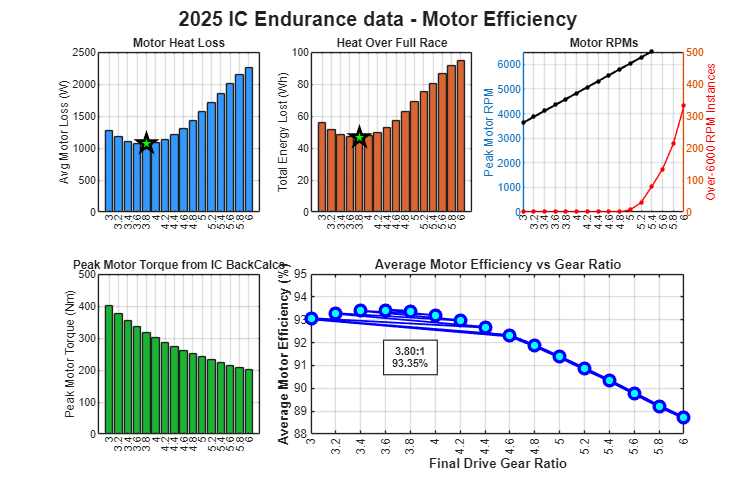


colRPM    = find(contains(lower(tbl.Properties.VariableNames),'rpm'),1);
colTorque = find(contains(lower(tbl.Properties.VariableNames),{'torque','trq','nm'}),1);
colPower  = find(contains(lower(tbl.Properties.VariableNames),{'power','w'}),1);

RPM_base    = tbl{:,colRPM};
Torque_base = tbl{:,colTorque};

% FIXED: Added missing 'end'
if isempty(colPower)
    PowerW_base = Torque_base .* (RPM_base * pi / 30);   % P = T * ω
else
    PowerW_base = tbl{:,colPower};
end

%% Results table — now includes average efficiency
results = table('Size',[length(newGRs),7], ...
    'VariableTypes',{'double','double','double','double','double','double','double'}, ...
    'VariableNames',{'GearRatio','AvgPowerLoss_W','TotalEnergyLoss_Wh','TruncatedPoints','MaxRPM','PeakTorque_Nm','AvgEfficiency_Percent'});
results.GearRatio = newGRs(:);

if exist(outputFile,'file'), delete(outputFile); end

%% MAIN SWEEP — PHYSICALLY CORRECT
for i = 1:length(newGRs)
    GR = newGRs(i);
    
    RPM_new    = RPM_base  * (GR / baseGR);     % Higher GR → motor spins faster
    Torque_new = Torque_base * (baseGR / GR);   % Higher GR → lower motor torque
    
    results.MaxRPM(i)        = max(RPM_new);
    results.PeakTorque_Nm(i) = max(Torque_new);
    overRevCount             = sum(RPM_new > RPM_limit);
    valid                    = RPM_new <= RPM_limit;
    
    RPM_new    = RPM_new(valid);
    Torque_new = Torque_new(valid);
    PowerMech  = PowerW_base(valid);
    
    rpm_c = max(min(RPM_new,   max(rpm_vals)),   min(rpm_vals));
    trq_c = max(min(Torque_new,max(torque_vals)),min(torque_vals));
    eff   = interp2(rpm_vals, torque_vals, efficiencyGrid, rpm_c, trq_c, 'linear', 90);
    
    PowerLoss_W = PowerMech ./ (eff/100) - PowerMech;
    dt = 0.02;
    
    results.AvgPowerLoss_W(i)         = mean(PowerLoss_W);
    results.TotalEnergyLoss_Wh(i)     = sum(PowerLoss_W)*dt/3600;
    results.TruncatedPoints(i)        = overRevCount;
    results.AvgEfficiency_Percent(i)  = mean(eff);  % Average efficiency for this ratio
    
    T = table(RPM_new, Torque_new, PowerMech, eff, PowerLoss_W, ...
        'VariableNames',{'RPM','Torque_Nm','Power_Mech_W','Efficiency_%','PowerLoss_W'});
    sheet = strrep(sprintf('GR_%.1f',GR),'.0','');
    writetable(T, outputFile, 'Sheet',sheet, 'WriteMode','append');
end

%% Ranking
results = sortrows(results,'AvgPowerLoss_W');
results.Rank = (1:height(results))';
results.Status = repmat("SAFE",height(results),1);
results.Status(results.TruncatedPoints>0  & results.TruncatedPoints<200) = "RISKY";
results.Status(results.TruncatedPoints>=200) = "DANGEROUS";
writetable(results, outputFile, 'Sheet','Summary', 'WriteMode','append');

%% 5-PANEL FIGURE + EFFICIENCY PLOT
figure('Position',[50 50 1400 900],'Color','w');

% Panel 1: Motor Loss
subplot(2,3,1)
bar(results.GearRatio, results.AvgPowerLoss_W, 'FaceColor',[0.2 0.6 1]);
ylabel('Avg Motor Loss (W)','FontSize',10);
title('Motor Heat Loss','FontWeight','bold');
grid on; box on;
set(gca,'XTick',newGRs,'XTickLabelRotation',90,'FontSize',8);

% Panel 2: Total Energy Lost
subplot(2,3,2)
bar(results.GearRatio, results.TotalEnergyLoss_Wh, 'FaceColor',[0.85 0.4 0.2]);
ylabel('Total Energy Lost (Wh)','FontSize',10);
title('Heat Over Full Race','FontWeight','bold');
grid on; box on;
set(gca,'XTick',newGRs,'XTickLabelRotation',90,'FontSize',8);

% Panel 3: RPM 
subplot(2,3,3)
yyaxis left
plot(results.GearRatio, results.MaxRPM, 'k.-', 'MarkerSize',10, 'LineWidth',1.5);
ylabel('Peak Motor RPM','FontSize',10); ylim([0 6500]);
yyaxis right
plot(results.GearRatio, results.TruncatedPoints, 'r.-', 'MarkerSize',10);
ylabel('Over-6000 RPM Instances','Color','r','FontSize',10);
ylim([0 500]); yticks(0:100:500);
yline(RPM_limit,'--r','6000 RPM Limit');
title('Motor RPMs','FontWeight','bold');
grid on; box on;
set(gca,'XTick',newGRs,'XTickLabelRotation',90,'FontSize',8);

% Panel 4: Peak Motor Torque
subplot(2,3,4)
bar(results.GearRatio, results.PeakTorque_Nm, 'FaceColor',[0.1 0.7 0.2]);
ylabel('Peak Motor Torque (Nm)','FontSize',10);
title('Peak Motor Torque from IC BackCalcs','FontWeight','bold');
grid on; box on;
set(gca,'XTick',newGRs,'XTickLabelRotation',90,'FontSize',8);

% Panel 5: Gear Ratio vs Average Efficiency
subplot(2,3,[5 6])
plot(results.GearRatio, results.AvgEfficiency_Percent, 'bo-', ...
    'MarkerFaceColor','cyan','MarkerSize',8,'LineWidth',2.5);
ylabel('Average Motor Efficiency (%)','FontSize',11,'FontWeight','bold');
xlabel('Final Drive Gear Ratio','FontSize',11,'FontWeight','bold');
title('Average Motor Efficiency vs Gear Ratio','FontWeight','bold','FontSize',12);
grid on; box on;
set(gca,'XTick',newGRs,'XTickLabelRotation',90,'FontSize',9);
ylim([floor(min(results.AvgEfficiency_Percent)), ceil(max(results.AvgEfficiency_Percent)*1.01)]);

% Main title
sgtitle(sprintf('2025 IC Endurance data - Motor Efficiency' ), ...
    'FontSize',15, 'FontWeight','bold');

%% Highlight best SAFE ratio
safeIdx = results.TruncatedPoints == 0;
if any(safeIdx)
    bestGR = results.GearRatio(safeIdx);
    bestGR = bestGR(1);
    
    subplot(2,3,1); hold on; 
    plot(bestGR, results.AvgPowerLoss_W(results.GearRatio==bestGR), ...
        'p','MarkerFaceColor','green','MarkerEdgeColor','k','MarkerSize',14,'LineWidth',2);
    
    subplot(2,3,2); hold on; 
    plot(bestGR, results.TotalEnergyLoss_Wh(results.GearRatio==bestGR), ...
        'p','MarkerFaceColor','green','MarkerEdgeColor','k','MarkerSize',14,'LineWidth',2);
    
    subplot(2,3,[5 6]); hold on;
    %plot(bestGR, results.AvgEfficiency_Percent(results.GearRatio==bestGR), ...
        %'p','MarkerFaceColor','yellow','MarkerEdgeColor','k','MarkerSize',4,'LineWidth',3);
    text(bestGR, results.AvgEfficiency_Percent(results.GearRatio==bestGR) - 2, ...
        sprintf(' %.2f:1 \n %.2f%% ', bestGR, results.AvgEfficiency_Percent(results.GearRatio==bestGR)), ...
        'HorizontalAlignment','center','FontWeight','bold','FontSize',8, ...
        'BackgroundColor','white','EdgeColor','k','Margin',4);
end